# Расстояние между функциями

## Красницкий Никита

clear all
close all
clc

Time = 2;           % Time of signals 2 sec
Fs   = 100;         % Sampling frequency 100Hz
dt   = 1/Fs;        % Time step

t = 0:dt:Time-dt;      % Time reprosontation

Создаю две функции

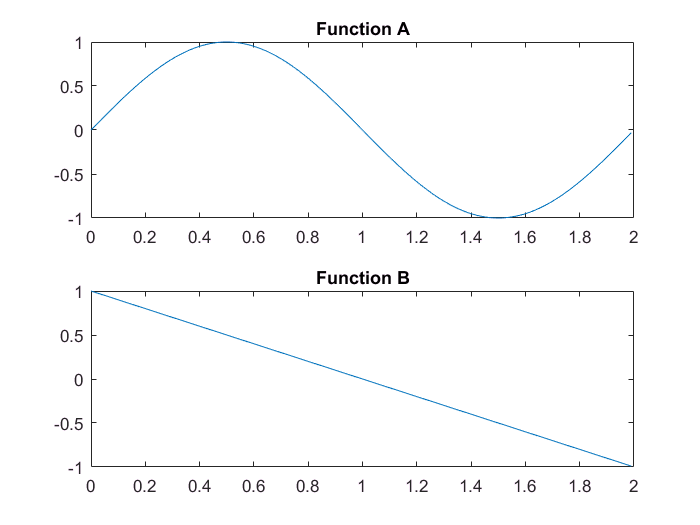

w0 = 2*pi/Time;
A  = sin(w0*t);
B  = 1 - t;

figure
subplot(2,1,1);
plot(t, A);
title('Function A');
subplot(2,1,2);
plot(t, B);
title('Function B');

Квадрат функций

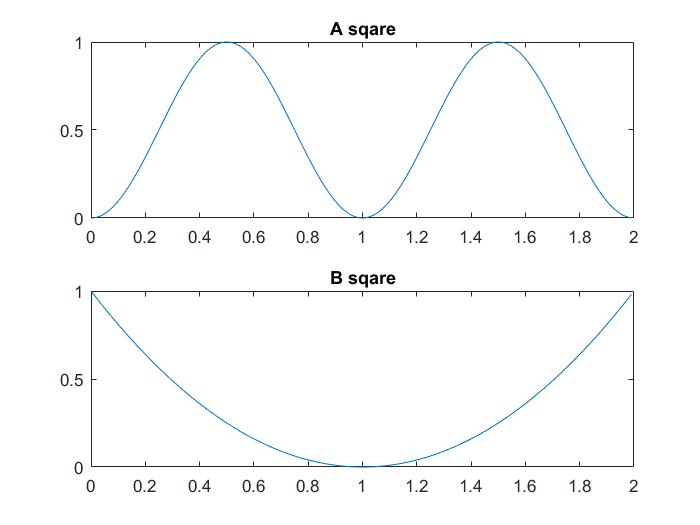

SqA = A.*A;
SqB = B.*B;

figure
subplot(2,1,1);
plot(t, SqA);
title('A sqare');
subplot(2,1,2);
plot(t, SqB);
title('B sqare')

Норма функций. Подобие интеграла.

NormA = sqrt(sum(SqA * dt));
NormB = sqrt(sum(SqB * dt));

Преобразование функций к нормированному виду

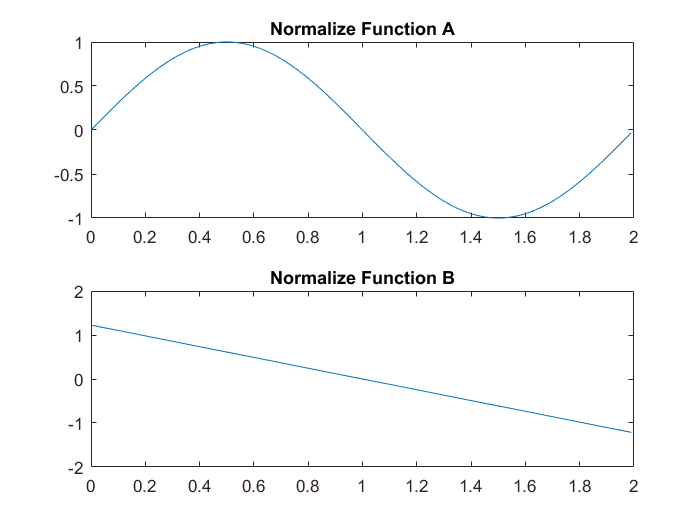

A = A/NormA;
B = B/NormB;

figure
subplot(2,1,1);
plot(t, A);
title('Normalize Function A');
subplot(2,1,2);
plot(t, B);
title('Normalize Function B');

Общий вид функций и графическое изображение разницы функций

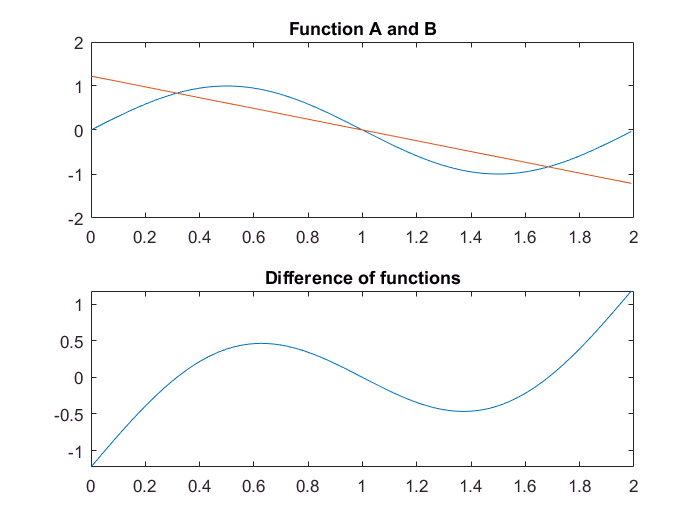

FunDif = A - B;

figure
subplot(2,1,1);
plot(t, A);
hold on
plot(t, B);
hold off
title('Function A and B');
subplot(2,1,2);
plot(t, FunDif);
title('Difference of functions');
ylim([min(FunDif) max(FunDif)]);

Расстояние между функциями

FunDistance = sum(FunDif.*FunDif * dt);
disp('Distance between function is ');

Distance between function is 


disp(FunDistance);

    0.4408

